clear;
clc;
addpath("../interpolation/")
addpath("../../Optimal Control/cart_pole/")

% m1 = 2.0;  % (kg) Cart mass
% m2 = 0.5;  % (kg) pole mass
% l = 0.5;   % (m) pendulum (pole) length
% 
% dist = 0.8;  %How far must the cart translate during its swing-up
% maxForce = 100;  %Maximum actuator forces
% duration = 2;

m1 = 5;  % (kg) Cart mass
m2 = 1;  % (kg) pole mass
l = 2;   % (m) pendulum (pole) length

dist = 0.8;  %How far must the cart translate during its swing-up
maxForce = 200;  %Maximum actuator forces
duration = 2;

## Objective

times = 0:0.1:duration;
len = size(times, 2);
force_square_obj = @(x) trapz(times,x(4*len+1:5*len).^2);

## Formulation

LB = [ones(len, 1)*(-2*dist); ones(len, 1)*(-2*pi); ones(len, 1)*(-inf); ...
    ones(len, 1)*(-inf); ones(len, 1)*(-maxForce)]; %Lower Bounds

UB = [ones(len, 1)*(2*dist); ones(len, 1)*(2*pi); ones(len, 1)*(inf); ...
    ones(len, 1)*(inf); ones(len, 1)*(maxForce)]; %Upper Bounds

target = [dist, pi, 0, 0];

X0 = [transpose(times*target(1)/duration); transpose(times*target(2)/duration); ...
    zeros(len, 1); zeros(len, 1); zeros(len, 1)]; %Initial Condition

A = []; %No linear inequality constraints
B = [];

Aeq = []; %No linear equality constraints
Beq = [];

options = optimoptions('fmincon',...
                       'Algorithm', 'sqp',...
                       'Display', 'iter-detailed',...
                       'MaxFunctionEvaluations', 100000,...
                       'MaxIterations', 2000,...
                       'FunctionTolerance', 1e-10);

## Solve NLP

[X, Cost] = fmincon(@(x) force_square_obj(x), X0, A, B, Aeq, Beq, LB, UB,...
            @(x) trapezoidal_constraints(x, m1, m2, l, times, target), options);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         106    0.000000e+00     4.885e-01     1.000e+00     0.000e+00     1.490e-09  
    1         212    9.899014e-01     1.758e+00     1.000e+00     1.081e+01     2.131e+02  
    2         318    5.267447e+03     1.170e+00     1.000e+00     2.313e+02     5.098e+03  
    3         425    1.547923e+04     5.038e-01     7.000e-01     2.302e+02     6.397e+03  
    4         531    3.531099e+04     2.864e-01     1.000e+00     3.439e+02     1.438e+04  
    5         637    4.931633e+04     9.656e-02     1.000e+00     3.042e+02     1.646e+04  
    6         743    5.339135e+04     6.445e-02     1.000e+00     1.531e+02     1.678e+04  
    7         849    4.524195e+04     6.464e-03     1.000e+00     1.078e+02     1.695e+04  
    8         955    4.122403e+04     1.148e-02     1.000e+00     1.123e+02     1.

## Plot

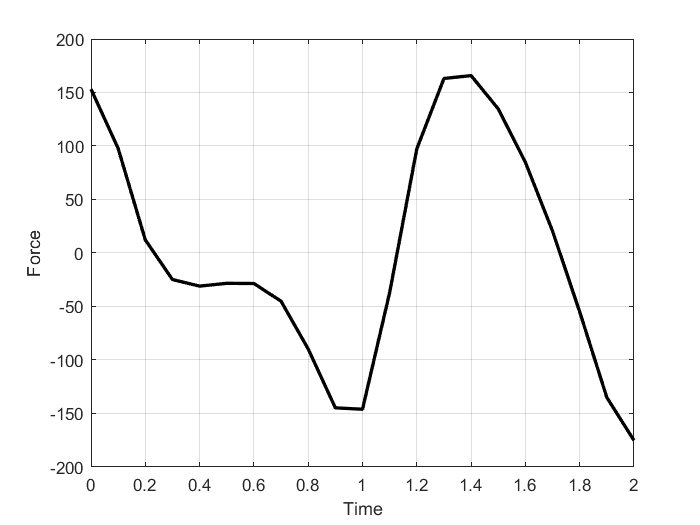

q1 = X(1:len);
q2 = X(len+1:2*len);
q1_d = X(2*len+1:3*len);
q2_d = X(3*len+1:4*len);
u = X(4*len+1:5*len);

figure(1);
plot(times, u,'k', 'LineWidth', 2);
axis auto;
grid on;
xlabel('Time');
ylabel('Force');

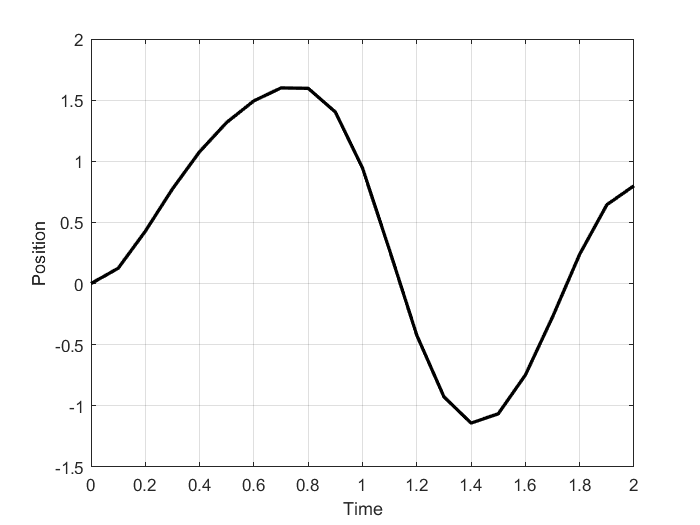


figure(2);
plot(times, q1,'k', 'LineWidth', 2);
grid on;
xlabel('Time');
ylabel('Position');

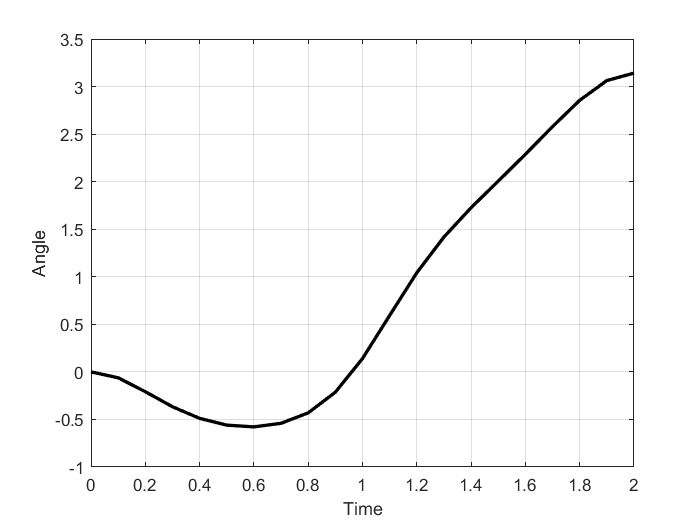


figure(3);
plot(times, q2,'k', 'LineWidth', 2);
grid on;
xlabel('Time');
ylabel('Angle');

## Interpolation

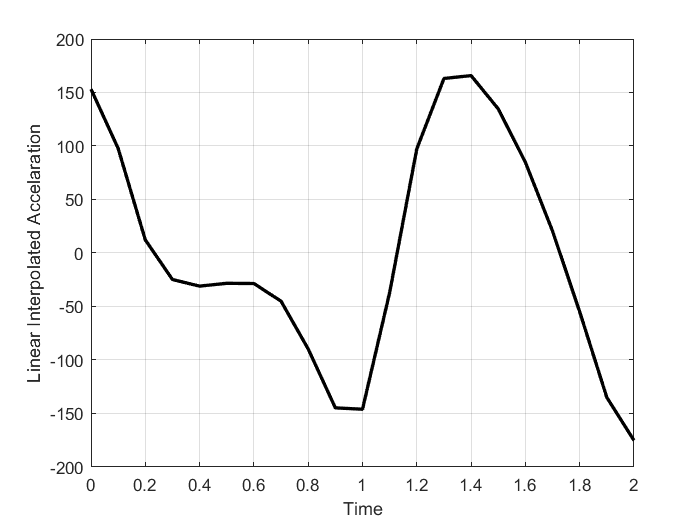

tm = 0:0.02:duration;

u_i = [];
for i = 1:size(tm, 2)
    u_i = [u_i, linear_interpolate(times, u, tm(i))];
end
figure(4);
plot(tm, u_i, 'k', 'LineWidth', 2);
grid on;
xlabel('Time');
ylabel('Linear Interpolated Accelaration');

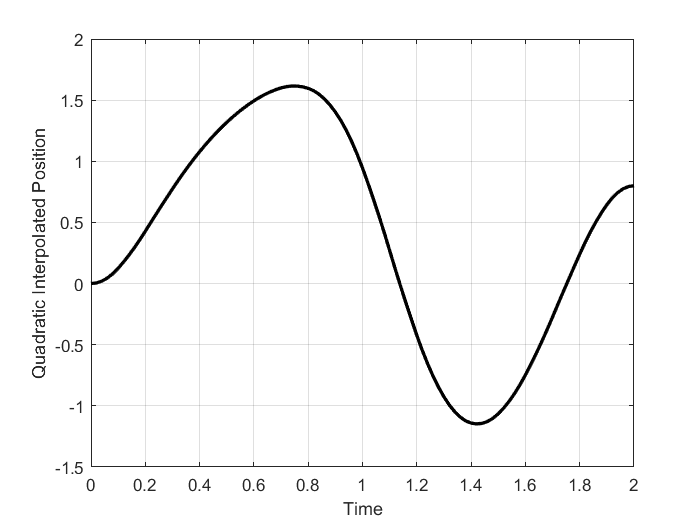


q1_i = [];
for i = 1:size(tm, 2)
    q1_i = [q1_i, quadratic_interpolate(times, q1, q1_d, tm(i))];
end
figure(5);
plot(tm, q1_i, 'k', 'LineWidth', 2);
grid on;
xlabel('Time');
ylabel('Quadratic Interpolated Position');

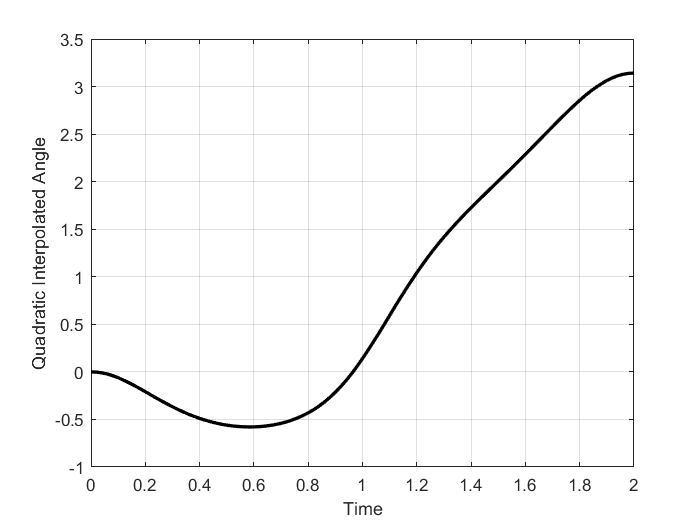


q2_i = [];
for i = 1:size(tm, 2)
    q2_i = [q2_i, quadratic_interpolate(times, q2, q2_d, tm(i))];
end
figure(6);
plot(tm, q2_i, 'k', 'LineWidth', 2);
grid on;
xlabel('Time');
ylabel('Quadratic Interpolated Angle');

## Simulation

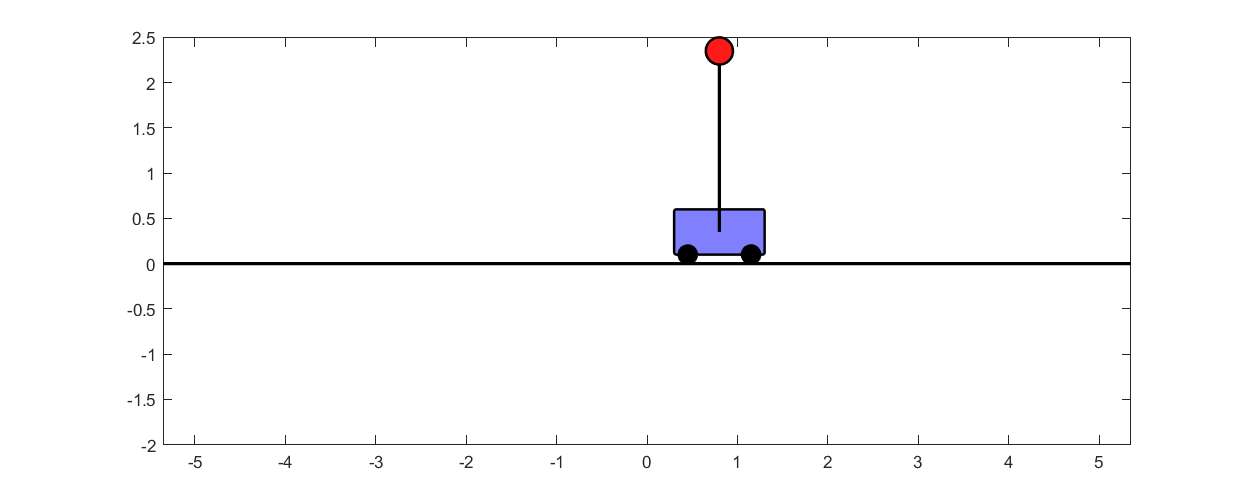

sim_data = [transpose(q1_i), transpose(q2_i)];
for k=1:1:size(tm, 2)
    drawpend(sim_data(k,:),m2,m1,l);
end

## Reanimate and Save Video

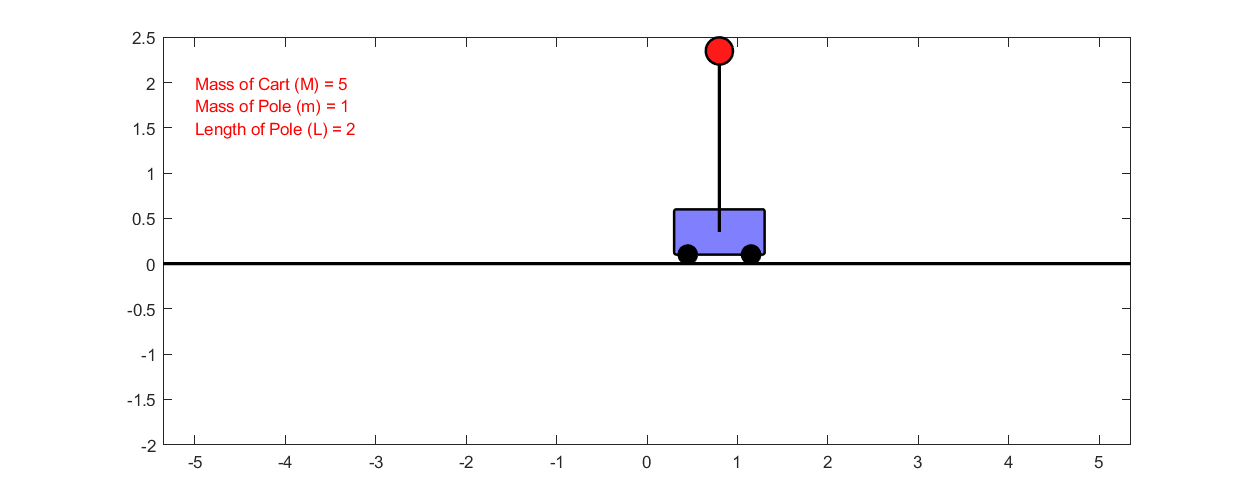

myMovie = anim_drawpend(tm, sim_data, m2, m1, l);

myWriter = VideoWriter('traj-cart-pole', 'MPEG-4');
myWriter.FrameRate = 10;

open(myWriter);
writeVideo(myWriter, myMovie);
close(myWriter);